!asiosettings();

'asiosettings' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 


!asiosettings();

'asiosettings' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 


clear;clf;
!rec = audiorecorder(48000,16,1);

'rec' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 


recduration = 1;
du = 0.2;
!recordblocking(rec,recduration);

'recordblocking' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 


!play(rec);

'play' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 


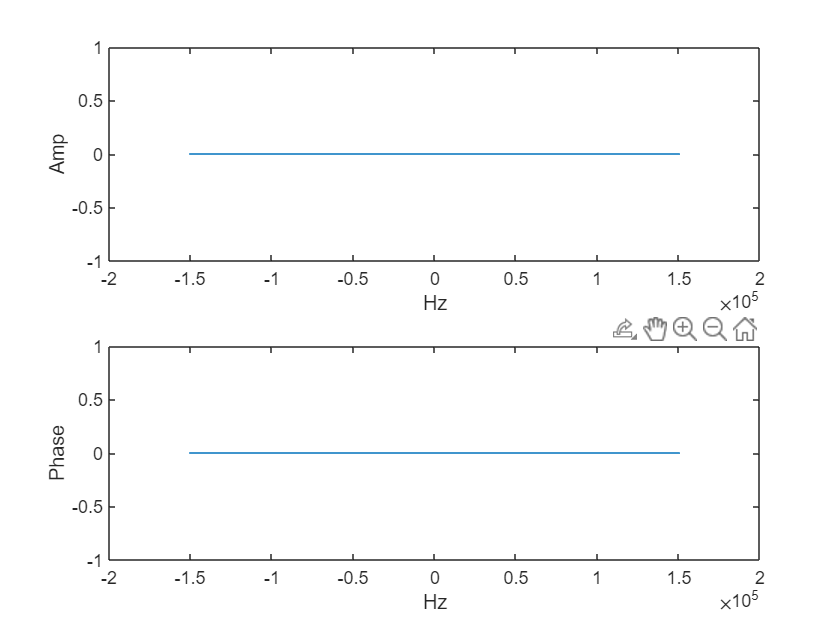

freqs = 4000:250:5500;
Fs = 48000;
One = genSinWave(5000,0,du,48000);
Zero = genSinWave(5000,pi,du,48000);
Ones = zeros([length(freqs) length(One)]);
Zeros = zeros([length(freqs) length(One)]);
Ones;
for i = 1:length(freqs)
    Ones(i,:) = genSinWave(freqs(i),0,du,48000);
    Zeros(i,:) = genSinWave(freqs(i),pi,du,48000);
end
mix = One;
for i = 1:length(freqs)
    mix = mix + Ones(i,:);
end
mix = Ones(1,:) + Ones(2,:) + Ones(3,:);
soundsc(mix);
rec2 = audiorecorder(48000,16,1);
recordblocking(rec2,recduration);
pause(1);
play(rec2);
y = getaudiodata(rec2);
wave = [0.2609558, 0.32052612, 0.3284912, 0.27548218, 0.14572144, -0.05895996, -0.27700806, -0.43234253, -0.49249268, -0.4432373, -0.2670288, 0.01727295, 0.31906128, 0.53396606, 0.5987549, 0.48349, 0.21469116, -0.10671997, -0.36416626, -0.49777222, -0.49624634, -0.35125732, -0.07394409, 0.25961304, 0.53619385, 0.661438, 0.57980347, 0.3088379, -0.037872314, -0.31747437, -0.4567566, -0.4547119, -0.32861328, -0.10827637, 0.143219, 0.33911133, 0.4116211, 0.3479004, 0.19320679, 0.016357422, -0.13812256, -0.25357056, -0.31933594, -0.32299805, -0.25897217, -0.13232422, 0.040222168, 0.22491455];
y = wave;
yfft = fft(y);
yfft = fftshift(yfft);
N=length(yfft);
for t = 1:N
    if(abs(yfft(t)) < 200)
        yfft(t) = 0;
    end
end
dFs = 2 * pi * linspace(0,Fs,N) - Fs / 2 * 2 * pi; 
subplot(2,1,1);
plot(dFs(1:length(yfft)),abs(yfft));
xlabel("Hz")
ylabel("Amp");
subplot(2,1,2);
plot(dFs(1:length(yfft)),angle(yfft));
xlabel("Hz");
ylabel("Phase");

sum(Ones(1,:) .* mix)

ans = 4.8000e+03

sum(Zeros(1,:) .* mix)

ans = -4.8000e+03

function ret = genSinWave(freqHz,phaseRad,lengthSec,Fs)
    t=0:1/Fs:lengthSec;
    ret = sin(2 * pi * freqHz .* t + phaseRad);
end